# PRÁCTICA EVALUABLE

En este script se resuelven los ejercicios C.1 (incluyendo el BONUS) y C.2, utilizando exclusivamente l

as funciones y métodos vistos en las sesiones prácticas del Lab1 al Lab6.

## **EJERCICIO C.1: COLORES PREDOMINANTES**

% C.1 (Enunciado)
% Define una función que tenga como inputs una imagen RGB y 
% un numero entero 1 <= n. Dicha funcion ha de devolver los n colores 
% predominantes en la imagen RGB pasada como input (tanto como n vectores 
% de tres coordenadas, como un pequeno recuadro de 50x50 de dicho color).

% BONUS -> Hay al menos dos estrategias diferentes para resolver este 
% ejercicio. Encuentra e implementa ambas.

%--------------------------------------------------------------------------
% EstrategIA 1: Clustering con K-Means

% En el Laboratorio 5 tratamos con el algoritmo `kmeans` para segmentar
% una imagen en 'k' clases. Hemos pensado que para este ejercicio podemos 
% aplicar esta misma lógica al espacio de color.

% Tratamos cada píxel como un punto de datos en un espacio 3D (R, G, B).
% El algoritmo `kmeans` agrupará estos puntos en 'n' clusters. Los
% centroides de estos 'n' clusters serán nuestros 'n' colores predominantes.

% Función para la estrategia 1:
function recuadros = encontrarColores_kmeans(imagenRGB, n)
    
    % Convertimos la imagen a tipo 'double' para que kmeans funcione.
    img_double = double(imagenRGB);
    
    % Generamos una matriz con una fila para cada pixel con los tres
    % valores de color de cada uno
    R_canal = img_double(:,:,1);
    G_canal = img_double(:,:,2);
    B_canal = img_double(:,:,3);
    
    % Esto crea la matriz (M*N) x 3
    pixeles = [R_canal(:), G_canal(:), B_canal(:)];
    
    % Aplicamos k-means donde 'C' contendrá los 'n' centroides [R,G,B] de los clusters.
    % Estos centroides SON nuestros colores predominantes.
    % Usamos 'Replicates' para asegurar un resultado más estable,
    % ya que k-means puede caer en mínimos locales.
    [~, C] = kmeans(pixeles, n);
    
    % A continuación devolvemos los n colores como vectores [R, G, B]
    % Los centroides 'C' ya están en formato [R, G, B] (rango 0-255).
    colores_rgb = uint8(C); % Convertimos de double a uint8
    
    % Finalmente generamos un 'cell array' (ya que nos permite guardar las multiples matrices'
    % para devolver pequeños recuadros de 50x50 donde almacenaremos los colores resultantes.
    recuadros = cell(n, 1);
    for i = 1:n
        % Extraemos el color del centroide 'i'
        color_vector = colores_rgb(i, :);
        
        % Creamos 3 planos de 50x50
        R_plane = zeros(50, 50, 'uint8'); R_plane(:,:) = color_vector(1);
        G_plane = zeros(50, 50, 'uint8'); G_plane(:,:) = color_vector(2);
        B_plane = zeros(50, 50, 'uint8'); B_plane(:,:) = color_vector(3);

        % Los unimos en la 3ª dimensión (usando 'cat')
        recuadro = cat(3, R_plane, G_plane, B_plane);
        
        % Guardamos el recuadro
        recuadros{i} = recuadro;
    end
    
end

% ---
% Estrategia 2 (BONUS): Análisis del Histograma de Tono (H) (Basado en P1)

% Para el BONUS, hemos pensado que pedemos usar una estrategia diferente basada en las funciones
% vistas en la práctica del Laboratorio 1: `rgb2hsv` e `imhist`.

% En este caso en lugar de analizar el espacio RGB, analizamos el espacio HSV. El
% canal 'H' (Hue o Tono) representa el "color" puro.

% Los pasos que hemos previsto seguir son:
% 1. Convertir la imagen a HSV.
% 2. Calcular el histograma del canal 'H'.
% 3. Los 'n' picos más altos de este histograma representan los 'n'
%    tonos (colores) más frecuentes.

% Función para aplicar lo comentado:
function recuadros = encontrarColores_hist(imagenRGB, n)
    
    % Convertimos de RGB a HSV)
    img_hsv = rgb2hsv(imagenRGB);
    
    % Separamos los canales
    H = img_hsv(:,:,1); % Tono
    S = img_hsv(:,:,2); % Saturación
    V = img_hsv(:,:,3); % Valor
    
    % Filtramos los píxeles "no cromáticos" (grises, blancos, negros) creando una 
    % máscara para píxeles con suficiente color (Saturación > 0.2 y Valor > 0.1)
    mascara_color = (S > 0.2) & (V > 0.1);
    
    % Obtenemos solo los píxeles de Tono que tienen color
    pixeles_h = H(mascara_color);
    
    % Calculamos el histograma del Tono (H) usando 64 bins para agrupar los tonos 
    % y de esta manera evitar que nos pueda devolver 3 tonos de rojo casi identicos 
    % (por ejemplo) como los 3 colores más presentes en la imagen. De esta
    % manera nos aseguramos que los colores propuestos sean minimamente
    % diferentes.
    [counts, binLocations] = imhist(pixeles_h, 64);
    
    % Encontramos los 'n' picos 
    [~, indices_sort] = sort(counts, 'descend');
    
    % Obtenemos los 'n' bins más frecuentes
    indices_top = indices_sort(1:n);
    
    % Calculamos el valor central de H para esos bins
    tonos_predominantes = binLocations(indices_top);    

    % Inicializamos salidas para generar los recuadros con los colores como
    % en la estrategia anterior
    colores_rgb = zeros(n, 3, 'uint8');
    recuadros = cell(n, 1);

    for i = 1:n
        % Creamos un color representativo con el Tono (H) predominante
        % y Saturación (S) y Valor (V) altos por ejemplo 0.8
        h = tonos_predominantes(i);
        s = 0.8;
        v = 0.8;
        
        % Convertimos ese color [H,S,V] de vuelta a [R,G,B]
        color_hsv = [h, s, v];
        color_rgb_double = hsv2rgb(color_hsv);
        
        % Convertimos a uint8 (rango 0-255)
        color_vector = uint8(color_rgb_double * 255);
        colores_rgb(i, :) = color_vector;
                
        R_plane = zeros(50, 50, 'uint8'); R_plane(:,:) = colores_rgb(1);
        G_plane = zeros(50, 50, 'uint8'); G_plane(:,:) = colores_rgb(2);
        B_plane = zeros(50, 50, 'uint8'); B_plane(:,:) = colores_rgb(3);
        
        recuadro = cat(3, R_plane, G_plane, B_plane);

        recuadros{i} = recuadro;
    end
    
end

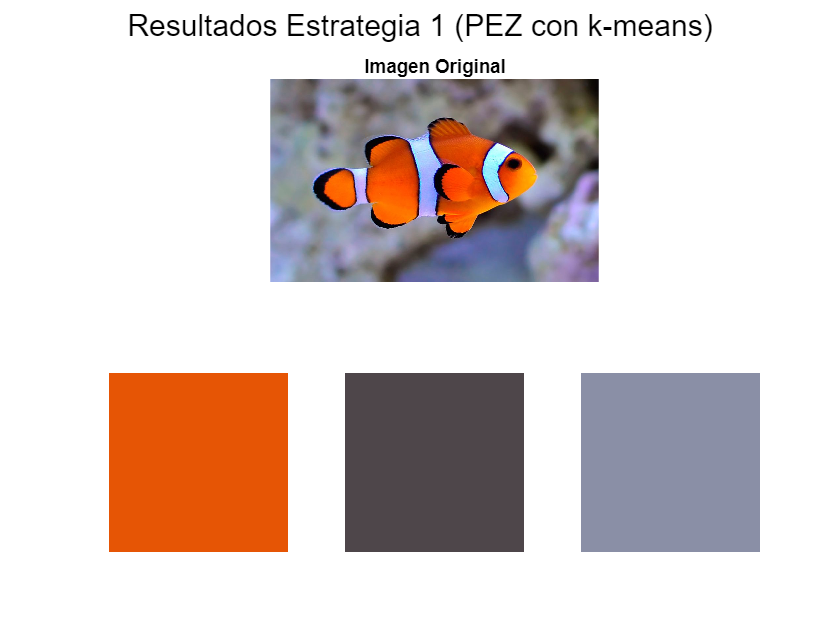

% Prueba de las funciones C.1

% Aquí probamos ambas funciones con una imagen y n=5.
% (Se recomienda usar una imagen propia o una de muestra como 'peppers.png')

% Provamos primero con una imagen de un pez payaso
pez = imread('pez.jpg');

% Definimos que encuentre 3 colores por ejemplo
n_colores = 3;

% --- Prueba Estrategia 1 (k-means) ---
recuadros1 = encontrarColores_kmeans(pez, n_colores);

% Mostrar resultados
figure('Name', 'Estrategia 1: k-means');
subplot(2, n_colores, 1:n_colores);
imshow(pez);
title('Imagen Original');

% Mostrar los recuadros de color
for i = 1:length(recuadros1)
    subplot(2, n_colores, n_colores + i);
    imshow(recuadros1{i});
end
sgtitle('Resultados Estrategia 1 (PEZ con k-means)');

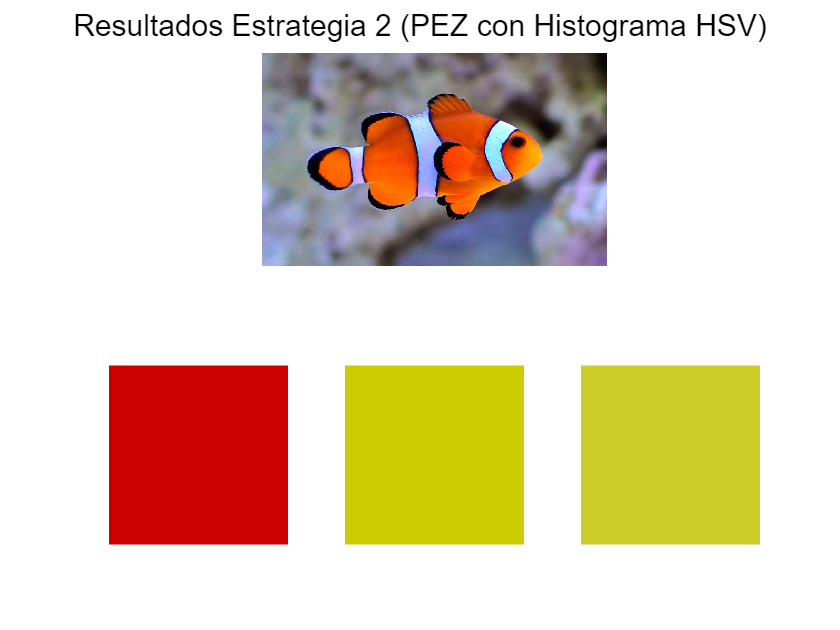

% En este caso vemos como se identifican con bastante satisfacción los
% colores más representativos de la imágen. Sobretodo el naranja del pez y
% tonos grises y oscuros muy probablemente del fondo.

% --- Prueba Estrategia 2 (Histograma HSV) ---
recuadros2 = encontrarColores_hist(pez, n_colores);

% Mostrar resultados
figure('Name', 'Estrategia 2: Histograma HSV');
subplot(2, n_colores, 1:n_colores);
imshow(pez);

% Mostrar los recuadros de color
if ~isempty(recuadros2)
    for i = 1:length(recuadros2)
        subplot(2, n_colores, n_colores + i);
        imshow(recuadros2{i});
    end
end
sgtitle('Resultados Estrategia 2 (PEZ con Histograma HSV)');

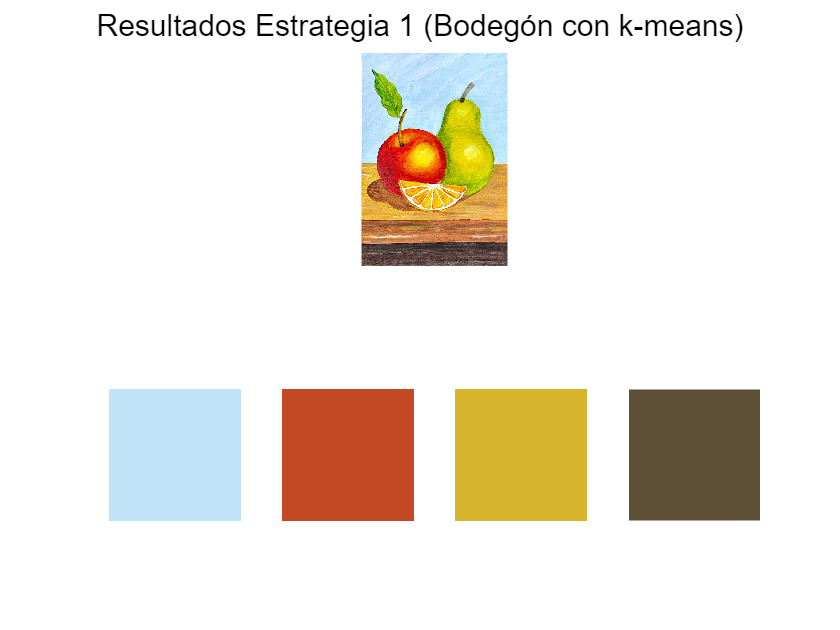

% En este caso vemos como el naranja tambien lo ha tomado bien (aunque
% debido a los valores fijos de 'value' y 'saturacion' lo ha mostrado más
% tirando a rojo. Por otro lado aun usando 64 bins vemos como el segundo y
% tercer color son practicamente iguales y es un amarillo que no
% identificamos en la imagen. Muy probablemente esto se deba a que es un
% color del fondo que al pasar por los valores fijos impuestos por la
% estrategia dos de v y s hace que suba mucho su intensidad mostrando
% colores que no aparecen explicitamente en la imagen.

% Esto en nuestra opinión hace que esta técnica pueda ser útil si lo que se
% desea es identificar tonos predominantes, pero en este caso presenta
% resultados considerablemente peores que la estrategia 1 con k-means.


% --- Prueba Estrategia 1 con otra foto ---

% Provamos ahora con otra imagen sobre un bodegon con la estrategia 1 que
% es la que mejores resultados a mostrado.

bodegon = imread("bodegon.jpg");

n_colores2 = 4;

recuadros1 = encontrarColores_kmeans(bodegon, n_colores2);

% Mostrar resultados
figure('Name', 'Foto Bodegón: k-means');
subplot(2, n_colores2, 1:n_colores2);
imshow(bodegon);

% Mostrar los recuadros de color
for i = 1:length(recuadros1)
    subplot(2, n_colores2, n_colores2 + i);
    imshow(recuadros1{i});
end
sgtitle('Resultados Estrategia 1 (Bodegón con k-means)');


% Como podemos ver de nuevo identifica los colores (en este caso 4) que le
% indicamos mostrando el color del fondo, de la manzana, un tono amarillo
% presente en las tres frutas y un marron oscuro muy probablemente de la
% parte oscura de la mesa. 

% Demostrando así como el metodo de k-means si que ha satisfecho las
% expectativas y ha funcionado correctamente a diferencia de la alternativa
% con el histograma.

## EJERCICIO C.2: EJES MAYOR Y MENOR

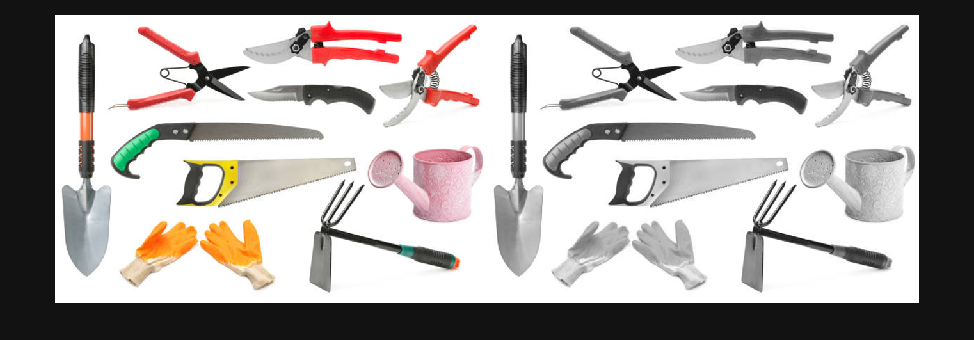

% C.2 (Enunciado)
% Escoge una o varias imagenes al azar en las que se vean al menos dos 
% objetos (...) lo suficientemente separadas como para segmentarlas 
% facilmente. Para cada una de ellas, calcular y mostrar sus ejes mayor y 
% menor. Para ello habra que usar el centroide, la medida de cada eje, y
% la orientacion de la componente conexa.

%-----------

% Para este ejercicio, usamos la segmentación vista en el laboratorio 5
% (`graythresh`, `imbinarize`, `bwlabel`) y los descriptores
% geométricos vistos en el 6 (`regionprops`).
%
% Según el enunciado de la practica se nos permite usar `regionprops` para
% 'Orientation', y en el lab 6 vimos cómo obtener 'Centroid', 'MajorAxisLength' y 'MinorAxisLength'.
% Usaremos exactamente esas propiedades.



% SOLUCIÓN PARA "HERRAMIENTAS" DE C.2
% 1. Cargar imagen
% Usamos 'objects.tif' o 'monedas.png' de las prácticas P5/P6.
% **CAMBIAR 'objects.tif' POR LA IMAGEN A EVALUAR**

img_objetos_rgb = imread('herramientas3.jpg');
%img_objetos_rgb = imgaussfilt(img_objetos_rgb,2);


% 2. Segmentación (Técnicas de P5)
% Aseguramos que sea escala de grises (visto en P1)
img_adjusted = img_objetos_rgb;
if size(img_adjusted, 3) == 3
    img_gray = rgb2gray(img_adjusted);
else
    img_gray = img_adjusted;
end
montage({img_objetos_rgb,img_gray})

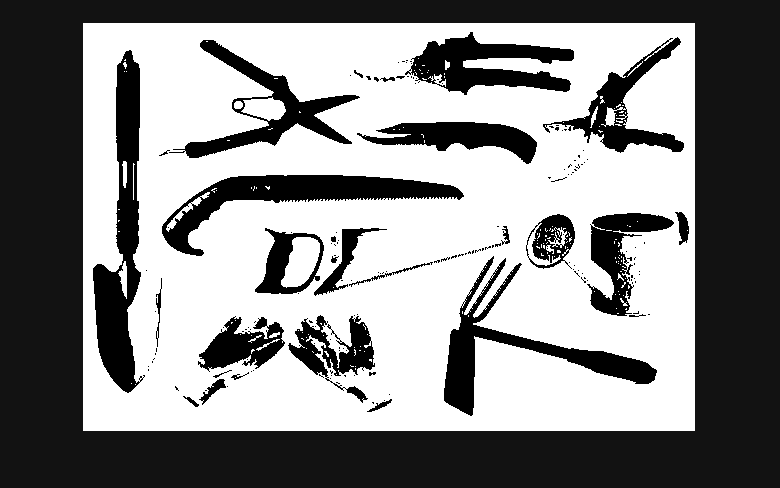

%realizamos segmentacion por threeshold, pero vemos que no queda bien
%definido
T = graythresh(img_gray);
bw = imbinarize(img_gray, T);
imshow(bw)

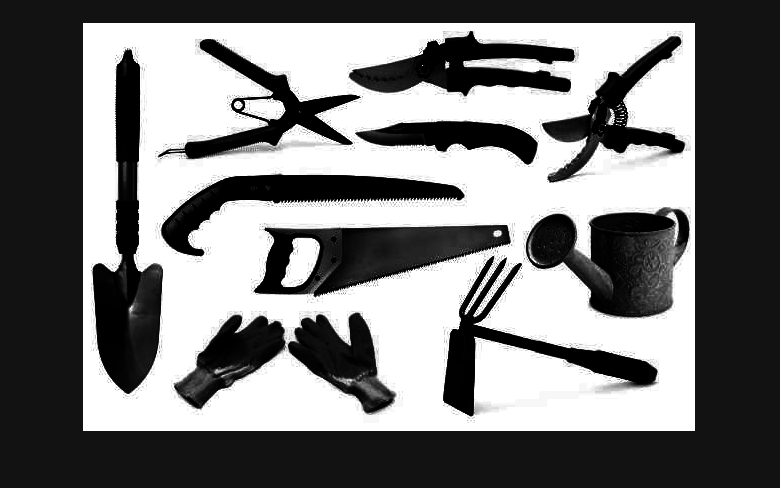

%podriamos buscar de forma manual un threeshold para detectar unicamente el
%fondo, pero aplicando una gamma para oscurecer las partes
%claras,aumentamos el contraste con el fondo
img = im2double(img_gray);
gamma = 9;
img_gamma = img .^ gamma;
img_gamma = mat2gray(img_gamma);

imshow(img_gamma);

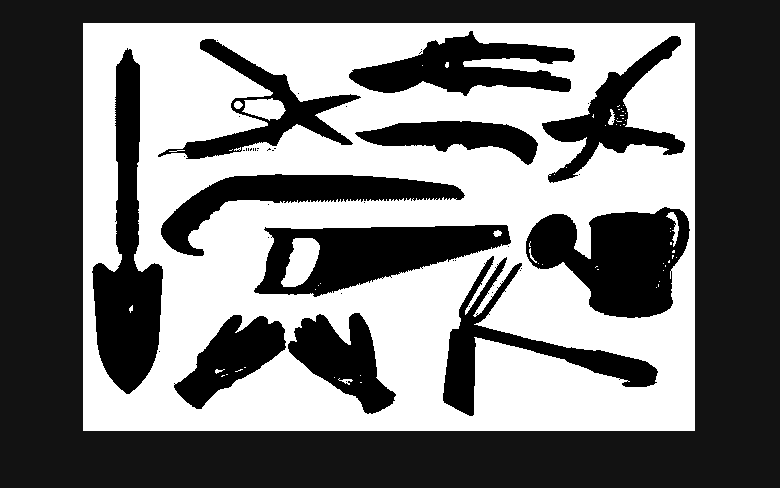

T = graythresh(img_gamma);
bw = imbinarize(img_gamma, T);
imshow(bw)

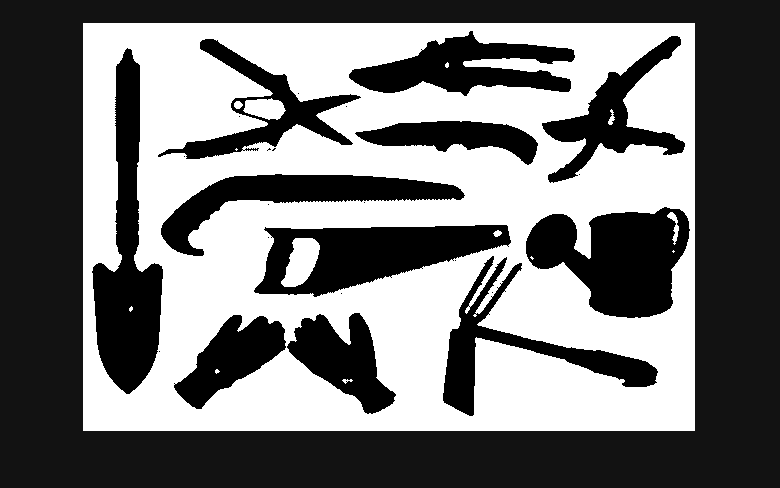

%han quedado correcctamente detectadas, pero aplicamos una apertura para
%juntar los pequeños trozos que han podido quedar separados. No podemos
%aplcicar mas, ya que sino el espacio entre los guantes se queda junto y no
%lo detecta como dos componentes conexas
bw_open = imopen(bw, strel('disk', 1));  % Estima el fondo
imshow(bw_open)

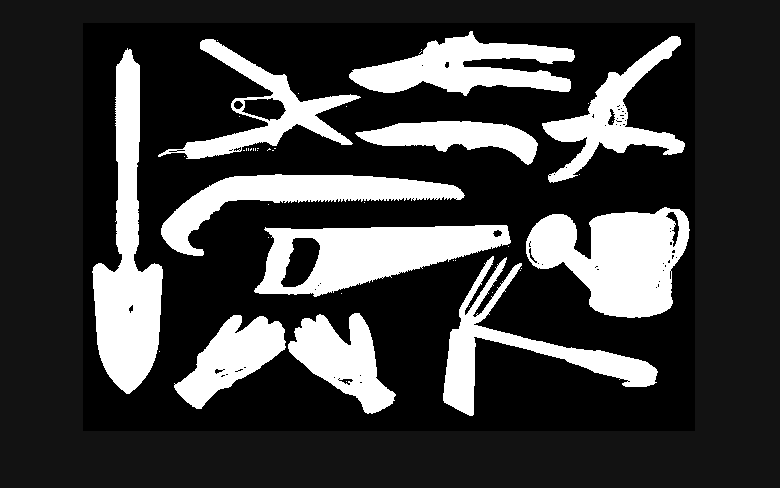


%los objetos son negros. Los invertimos para
% que los objetos sean blancos (necesario para bwlabel/regionprops).
% Comprobamos si el fondo (el valor más común) es blanco.
if mode(bw(:)) == 1 
    bw = not(bw);
end
imshow(bw)

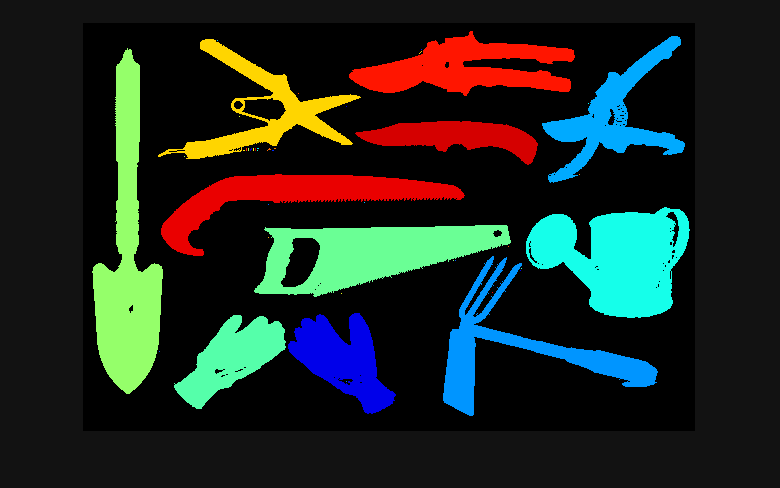


[L, numObjetos] = bwlabel(bw);
RGB_label = label2rgb(L, 'jet', 'k', 'shuffle'); 
imshow(RGB_label);

%vemos que ha quedado alguna componente conexa suelta, especialmente en las
%alicates de color naranja. 

CC = bwconncomp(bw);
stats = regionprops(CC, 'Area', 'Centroid')

stats = 45×1 struct array with fields:
    Area
    Centroid


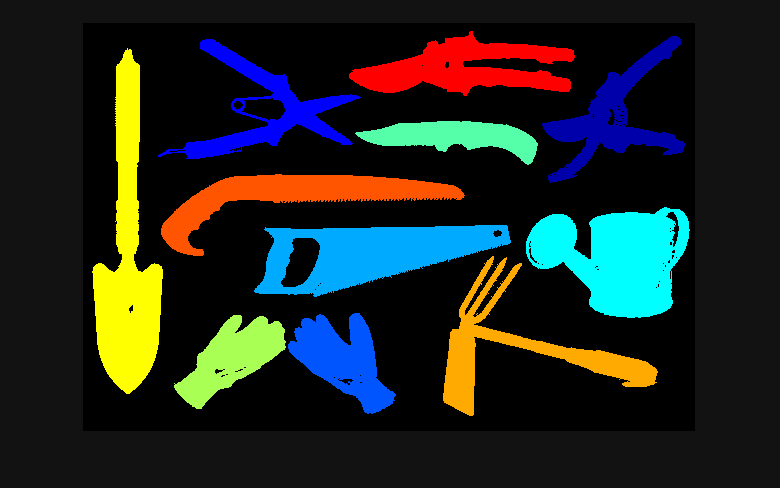

% como son formas con un area de maximo 10, las eliminamos con un
% bwareaopen
bw_clean = bwareaopen(bw, 10);


[L, numObjetos] = bwlabel(bw_clean);
RGB_label = label2rgb(L, 'jet', 'k', 'shuffle'); 
imshow(RGB_label);

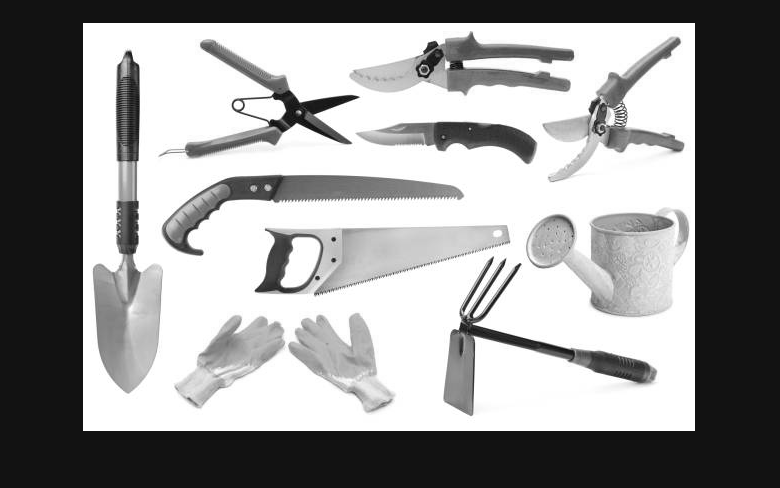


% 4. Cálculo de propiedades y visualización (Técnicas de P6)
% Mostramos la imagen original sobre la que dibujaremos

figure('Name', 'Ejercicio C.2 - Ejes de Objetos');
imshow(img_gray);
hold on; % Mantenemos la imagen para dibujar sobre ella

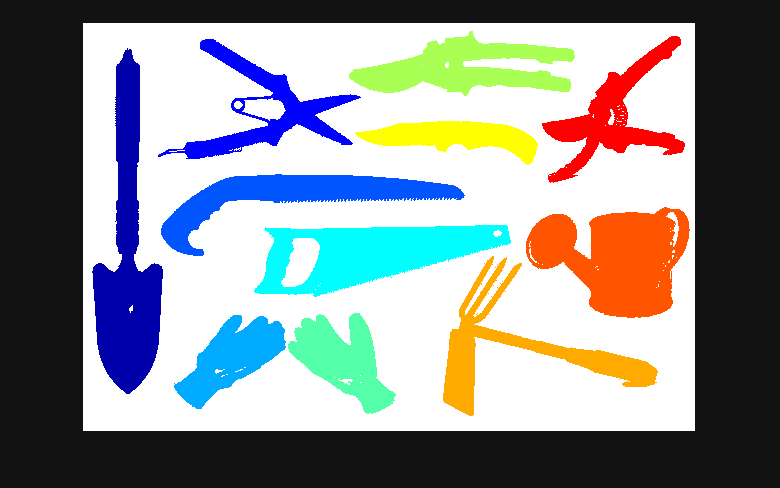

figure; imshow(label2rgb(L)); hold on;


figure; imshow(label2rgb(L)); hold on;
% a continuacion, iteraremos sobre las componentes para dibujar sus ejes
% respectivos. para ello, utilizamos los parametros de regionprops
% respectivos

for k = 1:numObjetos
    % Imagen binaria del objeto k
    comp_i = (L == k);

    % Propiedades
    stats = regionprops(comp_i, 'Centroid', 'MajorAxisLength', 'MinorAxisLength', 'Orientation');

    if isempty(stats)
        continue;
    end

    c = stats.Centroid;
    a = stats.MajorAxisLength / 2;  % semi-eje mayor
    b = stats.MinorAxisLength / 2;  % semi-eje menor
    theta = stats.Orientation;      % ángulo en grados

    fprintf('Objeto %d:\n', k);
    fprintf('  Centroide: (%.2f, %.2f)\n', c(1), c(2));
    fprintf('  Eje Mayor: %.2f\n', 2*a);
    fprintf('  Eje Menor: %.2f\n', 2*b);
    fprintf('  Orientación: %.2f grados\n', theta);

    % --- Dibujar el centroide ---
    plot(c(1), c(2), 'r+', 'MarkerSize', 10, 'LineWidth', 2);

    % --- Dibujar el eje mayor ---
    dx = a * cosd(-theta);
    dy = a * sind(-theta);
    line([c(1)-dx, c(1)+dx], [c(2)-dy, c(2)+dy], 'Color', 'green', 'LineWidth', 2);

    % --- Dibujar el eje menor (perpendicular) ---
    dx_perp = b * cosd(-theta + 90);
    dy_perp = b * sind(-theta + 90);
    line([c(1)-dx_perp, c(1)+dx_perp], [c(2)-dy_perp, c(2)+dy_perp], 'Color', 'red', 'LineWidth', 2);
end

Objeto 1:


  Centroide: (45.30, 234.56)


  Eje Mayor: 369.91


  Eje Menor: 58.61


  Orientación: -89.97 grados


Objeto 2:


  Centroide: (182.72, 87.73)


  Eje Mayor: 173.68


  Eje Menor: 125.22


  Orientación: 0.97 grados


Objeto 3:


  Centroide: (209.82, 174.89)


  Eje Mayor: 340.45


  Eje Menor: 57.29


  Orientación: 7.26 grados


Objeto 4:


  Centroide: (149.32, 335.44)


  Eje Mayor: 128.21


  Eje Menor: 54.59


  Orientación: 37.31 grados


Objeto 5:


  Centroide: (289.63, 231.10)


  Eje Mayor: 260.03


  Eje Menor: 64.17


  Orientación: 7.91 grados


Objeto 6:


  Centroide: (260.39, 337.32)


  Eje Mayor: 121.93


  Eje Menor: 67.82


  Orientación: -42.03 grados


Objeto 7:


  Centroide: (382.89, 45.45)


  Eje Mayor: 228.82


  Eje Menor: 55.77


  Orientación: 2.90 grados


Objeto 8:


  Centroide: (373.39, 114.37)


  Eje Mayor: 192.76


  Eje Menor: 31.65


  Orientación: -3.21 grados


Objeto 9:


  Centroide: (438.10, 326.39)


  Eje Mayor: 267.75


  Eje Menor: 134.60


  Orientación: -8.26 grados


Objeto 10:


  Centroide: (534.45, 235.92)


  Eje Mayor: 162.38


  Eje Menor: 110.08


  Orientación: -9.68 grados


Objeto 11:


  Centroide: (530.87, 94.78)


  Eje Mayor: 165.37


  Eje Menor: 98.14


  Orientación: 44.14 grados


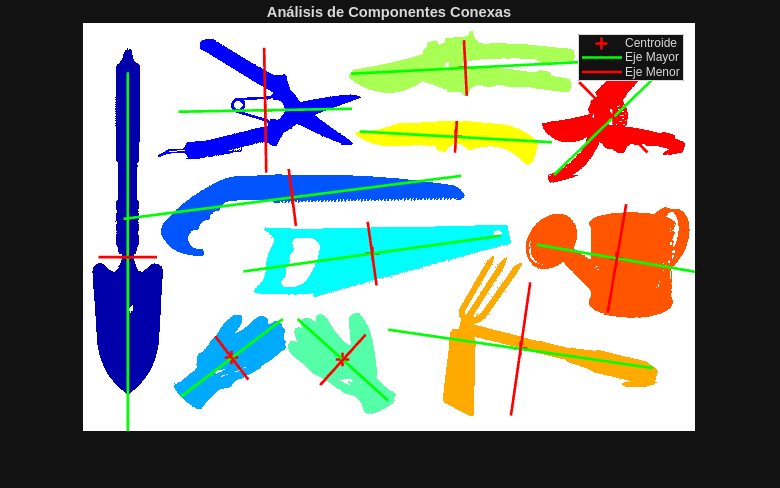





hold off; % Dejamos de dibujar
title('Análisis de Componentes Conexas');
legend('Centroide', 'Eje Mayor', 'Eje Menor');

% como podemos ver, se han generado correctamente los centroides y los ejes
% correspondientes a las imagenes.
% aun asi, algun elemento como la sierra azul o el rastrillo naranja, 
% quedan con su eje mayor que sobrepasa de su dimension real. Esto se debe
% a que al ser elementos irregulares, cuesta que sean de detectados de
% forma perfecta con la elipse de inercia de la imagen, y por eso quedan
% con su eje mayor un poco mas alejado de la cuenta en la banda donde hay
% la irregularidad




